clear; close all;

## 0. Initialize Parameters

L = 1200;                                           % Length of bridge
n = 1201;                                           % Discretize into 1 mm seg.
P = 400;                                            % a load number
x = linspace(0, L, n);                              % x-axis
x_train = [-856 -680 -516 -340 -176 0];             % Train Load Locations
P_train = [-1 -1 -1 -1 -1 -1]

P_train =     -1    -1    -1    -1    -1    -1


%P_train = [-1.1 -1.1 -1 -1 -1.485 -1.485] * P/6;    % Train load distribution
P_total = abs(sum(P_train));                        % Total weight of train [N]

## 1. SFD, BMD, SFE, BME

% BME and SFE initialize
SFE_x = zeros(2057, 1201);
BME_x = zeros(2057, 1201);

for start_pos = 1:2057  % start_pos = index of the bridge

% create load matrix
load_pos = x_train + start_pos - 1;
idx = load_pos >= 0 & load_pos <= 1200;
load_pos = load_pos(idx);
load = P_train(idx);

% calculate reaction forces
RB = -sum(load_pos .* load) / L;
RA = -sum(load) - RB;

% create load along bridge
load_x = zeros(1, 1201);
load_x(1) = RA;
load_x(n) = RB;
load_x(load_pos + 1) = load_x(load_pos + 1) + load;

% Construct SFD
SFD_x = zeros(1, n);
SFD_x(1) = load_x(1);
for i = 2:length(load_x)
    SFD_x(i) = SFD_x(i-1) + load_x(i);
end
% Initialize BMD_x
BMD_x = zeros(1, n);
% Compute cumulative sum of SFD_x excluding the first element
BMD_x(2:end) = cumsum(SFD_x(1:end-1));

% create envelop
SFD(start_pos, :) = SFD_x;
BMD(start_pos, :) = BMD_x;
end

SFD

SFD =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.9992   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   -0.0008   

BMD

BMD = 1.0e+03 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010  

% Finding the shear force envelope (taking the max of the absolute value)
% Find the maximum absolute value and the corresponding row index for each column
[maxAbsValues, rowIndices] = max(abs(SFD), [], 1);
SFE = SFD(sub2ind(size(SFD), rowIndices, 1:size(SFD, 2)))

SFE =     3.8550    3.8500    3.8450    3.8400    3.8350    3.8300    3.8250    3.8200    3.8150    3.8100    3.8050    3.8000    3.7950    3.7900    3.7850    3.7800    3.7750    3.7700    3.7650    3.7600    3.7550    3.7500    3.7450    3.7400    3.7350    3.7300    3.7250    3.7200    3.7150    3.7100    3.7050    3.7000    3.6950    3.6900    3.6850    3.6800    3.6750    3.6700    3.6650    3.6600    3.6550    3.6500    3.6450    3.6400    3.6350    3.6300    3.6250    3.6200    3.6150    3.6100


% Finding the bending moment envelope
BME = max(BMD, [], 1)

BME = 1.0e+03 *

         0    0.0039    0.0077    0.0115    0.0154    0.0192    0.0230    0.0268    0.0306    0.0343    0.0381    0.0419    0.0456    0.0493    0.0531    0.0568    0.0605    0.0642    0.0679    0.0715    0.0752    0.0789    0.0825    0.0861    0.0898    0.0934    0.0970    0.1006    0.1042    0.1077    0.1113    0.1149    0.1184    0.1219    0.1255    0.1290    0.1325    0.1360    0.1395    0.1429    0.1464    0.1499    0.1533    0.1567    0.1602    0.1636    0.1670    0.1704    0.1738    0.1771


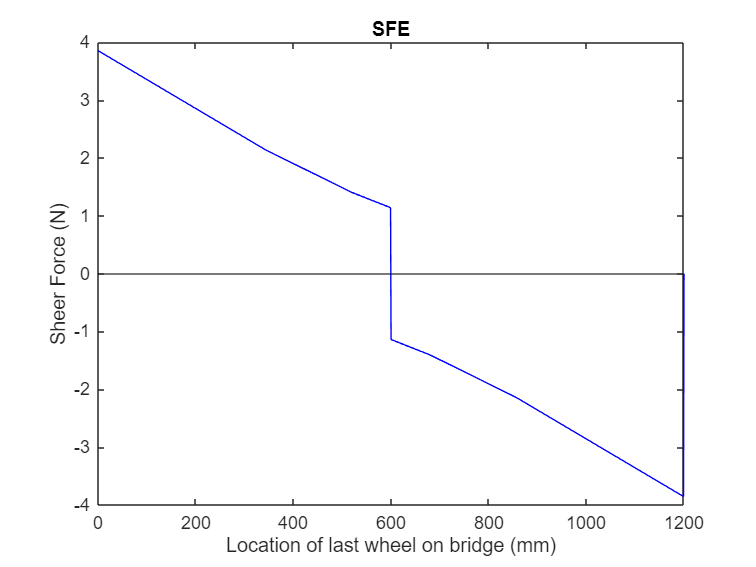

% plotting SFE
figure
plot(x, SFE, 'blue')
yline(0, 'black')
xlabel('Location of last wheel on bridge (mm)')
ylabel('Sheer Force (N)')
title('SFE')

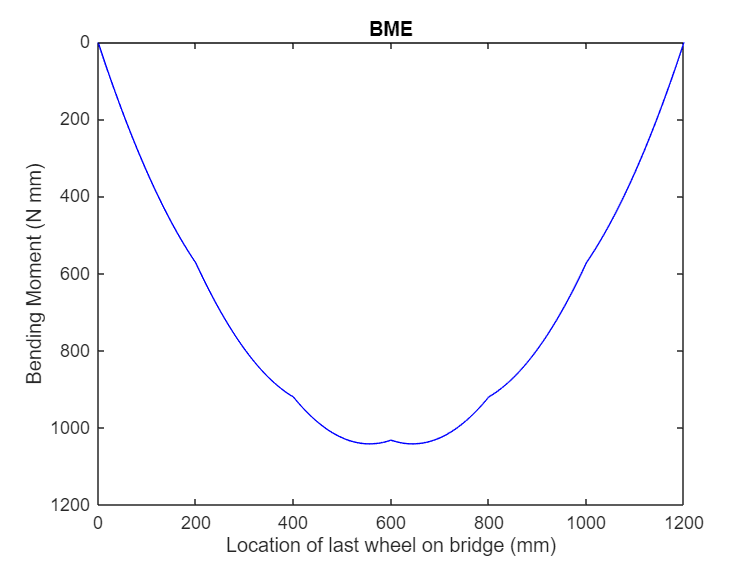

% plotting BME
figure
plot(x, BME, 'Blue')
yline(0, 'black')
xlabel('Location of last wheel on bridge (mm)')
ylabel('Bending Moment (N mm)')
title('BME')
set(gca, 'YDir', 'reverse')

## 2. `Define Bridge Parameters`

% Design 0 Parameters
xc = [0, 400, 800, L];                          % location where cross sections change
tfb = [100, 100, 100, 100];                     % top flange width b
tfh = [1.27, 1.27, 1.27, 1.27];                 % top flange height h
wb = [1.27, 1.27, 1.27, 1.27];                  % web width b
wh = [75, 75, 75, 75];                          % web height h
gtb = [5, 5, 5, 5];                             % glue tab width b
gth = [1.27, 1.27, 1.27, 1.27];                 % glub tab height h
bfb = [77.46, 77.46, 77.46, 77.46];             % bottom flange width b
bfh = [1.27, 1.27, 1.27, 1.27];                 % bottom flange height h
a = [400, 400, 400, 400];                       % diaphram spacing a

% extracting user input assuming linear relationship
tfb = interp1(xc, tfb, x);
tfh = interp1(xc, tfh, x);
wb = interp1(xc, wb, x);
wh = interp1(xc, wh, x);
gtb = interp1(xc, gtb, x);
gth = interp1(xc, gth, x);
bfb = interp1(xc, bfb, x);
bfh = interp1(xc, bfh, x);
a = interp1(xc, a, x);

## 3. Calculate Sectional Properties

[ybar, ytop, ybot, I, Qcent, Qglue] = properties(tfb, tfh, wb, wh, gtb, gth, bfb, bfh)

ybar =    41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311


ytop =    34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389


ybot =    41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311


I = 1.0e+05 *

    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835


Qcent = 1.0e+03 *

    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933


Qglue = 1.0e+03 *

    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439


## 4. Calculate Applied Stress

% material properties
sigmaT = 30;            % matboard tensile strength
sigmaC = 6;             % matboard compressive strength
tauM = 4;               % matboard sheer strength
Em = 4000;              % matboard young's modulus
Vm = 0.2;               % matboard poisson's ratio
tauG = 2;               % glue shear strength

% sigma compression = sigma top 
S_comp = BME .* ytop ./ I                           

S_comp =          0    0.0003    0.0006    0.0010    0.0013    0.0016    0.0019    0.0022    0.0025    0.0029    0.0032    0.0035    0.0038    0.0041    0.0044    0.0047    0.0050    0.0053    0.0057    0.0060    0.0063    0.0066    0.0069    0.0072    0.0075    0.0078    0.0081    0.0084    0.0087    0.0090    0.0093    0.0096    0.0099    0.0102    0.0104    0.0107    0.0110    0.0113    0.0116    0.0119    0.0122    0.0125    0.0128    0.0131    0.0133    0.0136    0.0139    0.0142    0.0145    0.0148


% sigma tension = sigma bottom
S_tens = BME .* ybot ./ I 

S_tens =          0    0.0004    0.0008    0.0011    0.0015    0.0019    0.0023    0.0027    0.0030    0.0034    0.0038    0.0041    0.0045    0.0049    0.0053    0.0056    0.0060    0.0064    0.0067    0.0071    0.0074    0.0078    0.0082    0.0085    0.0089    0.0092    0.0096    0.0100    0.0103    0.0107    0.0110    0.0114    0.0117    0.0121    0.0124    0.0128    0.0131    0.0135    0.0138    0.0142    0.0145    0.0148    0.0152    0.0155    0.0159    0.0162    0.0165    0.0169    0.0172    0.0175


% shear stress at centroid
t_cent = (SFE .* Qcent) ./ (I .* (wb .* 2)) 

t_cent =     0.0225    0.0224    0.0224    0.0224    0.0224    0.0223    0.0223    0.0223    0.0222    0.0222    0.0222    0.0221    0.0221    0.0221    0.0221    0.0220    0.0220    0.0220    0.0219    0.0219    0.0219    0.0219    0.0218    0.0218    0.0218    0.0217    0.0217    0.0217    0.0217    0.0216    0.0216    0.0216    0.0215    0.0215    0.0215    0.0214    0.0214    0.0214    0.0214    0.0213    0.0213    0.0213    0.0212    0.0212    0.0212    0.0212    0.0211    0.0211    0.0211    0.0210


% shear glue at tab
t_glue = (SFE .* Qglue) ./ (I .* (gtb .* 2))

t_glue =     0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0038    0.0038    0.0038    0.0038    0.0038    0.0038    0.0038    0.0038    0.0038    0.0038    0.0038    0.0038    0.0038    0.0038    0.0038    0.0038    0.0038    0.0038    0.0038    0.0037


## 5. Thin Plate Buckling Capcities

% case 1 thin plate buckling 
case1_b = bfb + wb;
S_buck1 = (4 * pi^2 * Em / (12 * (1 - Vm^2))) * (tfh ./ case1_b) .^2

S_buck1 =     3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669


% case 2 thin plate buckling
case2_b = (tfb - case1_b) ./ 2;
S_buck2 = (0.425 * (pi^2) * Em / (12 * (1 - Vm^2))) * (tfh ./ case2_b) .^2

S_buck2 =    20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696


% case 3 think plate buckling
case3_b = wh - ybar;
S_buck3 = (6 * (pi^2) * Em / (12 * (1 - Vm^2))) * (wb ./ case3_b) .^2

S_buck3 =    29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301   29.4301


% case 4 sheer buckling
T_buckV = (5 * (pi^2) * Em / (12 * (1 - Vm^2))) * ((wb ./ wh) .^2 + (wb ./a) .^2)

T_buckV =     5.0859    5.0859    5.0859    5.0859    5.0859    5.0859    5.0859    5.0859    5.0859    5.0859    5.0859    5.0859    5.0859    5.0859    5.0859    5.0859    5.0859    5.0859    5.0859    5.0859    5.0859    5.0859    5.0859    5.0859    5.0859    5.0859    5.0859    5.0859    5.0859    5.0859    5.0859    5.0859    5.0859    5.0859    5.0859    5.0859    5.0859    5.0859    5.0859    5.0859    5.0859    5.0859    5.0859    5.0859    5.0859    5.0859    5.0859    5.0859    5.0859    5.0859


## 6. FOS

FOS_tens = min(sigmaT ./ S_tens)

FOS_tens = 290.8055

FOS_comp = min(sigmaC ./ S_comp)

FOS_comp = 69.1663

FOS_shear = min(tauM ./ abs(t_cent))

FOS_shear = 178.0289

FOS_glue = min(tauG ./ abs(t_glue))

FOS_glue = 499.6527

FOS_buck1 = min(S_buck1 ./ S_comp)

FOS_buck1 = 41.1185

FOS_buck2 = min(S_buck2 ./ S_comp)

FOS_buck2 = 239.4263

FOS_buck3 = min(S_buck3 ./ S_comp)

FOS_buck3 = 339.2617

FOS_buckV = min(abs(T_buckV) ./ abs(t_cent))

FOS_buckV = 226.3594

## 7. Min FOS and Failure Load Pfail

% categorizing FOS
FOS = [FOS_tens, FOS_comp, FOS_buck1, FOS_buck2, FOS_buck3, FOS_shear, FOS_glue, FOS_buckV];
minFOS_overall = min(FOS);

% Calcuating the failure load
Pf = minFOS_overall * P_total

Pf = 246.7111

## 8. Vfail and Mfail

% 8.1 Matboard fail due to glue sheer
Vf_glue = tauG * I .* (2 * gtb) ./ Qglue

Vf_glue = 1.0e+03 *

    1.9262    1.9262    1.9262    1.9262    1.9262    1.9262    1.9262    1.9262    1.9262    1.9262    1.9262    1.9262    1.9262    1.9262    1.9262    1.9262    1.9262    1.9262    1.9262    1.9262    1.9262    1.9262    1.9262    1.9262    1.9262    1.9262    1.9262    1.9262    1.9262    1.9262    1.9262    1.9262    1.9262    1.9262    1.9262    1.9262    1.9262    1.9262    1.9262    1.9262    1.9262    1.9262    1.9262    1.9262    1.9262    1.9262    1.9262    1.9262    1.9262    1.9262


% 8.2 Matboard fail due to sheer
Vf_shear = tauM * I .* (2 * wb) ./ Qcent

Vf_shear =   686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013  686.3013


% 8.3 Matboard failing due to tension
% tension at bottom, so positive bending moment - why start at 0?
Mf_tens = sigmaT .* I ./ ybot

Mf_tens = 1.0e+05 *

    3.0293    3.0293    3.0293    3.0293    3.0293    3.0293    3.0293    3.0293    3.0293    3.0293    3.0293    3.0293    3.0293    3.0293    3.0293    3.0293    3.0293    3.0293    3.0293    3.0293    3.0293    3.0293    3.0293    3.0293    3.0293    3.0293    3.0293    3.0293    3.0293    3.0293    3.0293    3.0293    3.0293    3.0293    3.0293    3.0293    3.0293    3.0293    3.0293    3.0293    3.0293    3.0293    3.0293    3.0293    3.0293    3.0293    3.0293    3.0293    3.0293    3.0293


% 8.4 Matboard failing due to compression
Mf_comp = sigmaC .* I ./ ytop

Mf_comp = 1.0e+04 *

    7.2049    7.2049    7.2049    7.2049    7.2049    7.2049    7.2049    7.2049    7.2049    7.2049    7.2049    7.2049    7.2049    7.2049    7.2049    7.2049    7.2049    7.2049    7.2049    7.2049    7.2049    7.2049    7.2049    7.2049    7.2049    7.2049    7.2049    7.2049    7.2049    7.2049    7.2049    7.2049    7.2049    7.2049    7.2049    7.2049    7.2049    7.2049    7.2049    7.2049    7.2049    7.2049    7.2049    7.2049    7.2049    7.2049    7.2049    7.2049    7.2049    7.2049


% 8.5 Matboard failing due to local shear buckling
Vf_buckV = T_buckV .* I .* (2 * wb) ./ Qcent

Vf_buckV =   872.6155  872.6155  872.6155  872.6155  872.6155  872.6155  872.6155  872.6155  872.6155  872.6155  872.6155  872.6155  872.6155  872.6155  872.6155  872.6155  872.6155  872.6155  872.6155  872.6155  872.6155  872.6155  872.6155  872.6155  872.6155  872.6155  872.6155  872.6155  872.6155  872.6155  872.6155  872.6155  872.6155  872.6155  872.6155  872.6155  872.6155  872.6155  872.6155  872.6155  872.6155  872.6155  872.6155  872.6155  872.6155  872.6155  872.6155  872.6155  872.6155  872.6155


% 8.6 Matboard failding due to local buckling
Mf_buck1 = S_buck1 .* I ./ ytop

Mf_buck1 = 1.0e+04 *

    4.2832    4.2832    4.2832    4.2832    4.2832    4.2832    4.2832    4.2832    4.2832    4.2832    4.2832    4.2832    4.2832    4.2832    4.2832    4.2832    4.2832    4.2832    4.2832    4.2832    4.2832    4.2832    4.2832    4.2832    4.2832    4.2832    4.2832    4.2832    4.2832    4.2832    4.2832    4.2832    4.2832    4.2832    4.2832    4.2832    4.2832    4.2832    4.2832    4.2832    4.2832    4.2832    4.2832    4.2832    4.2832    4.2832    4.2832    4.2832    4.2832    4.2832


Mf_buck2 = S_buck2 .* I ./ ytop

Mf_buck2 = 1.0e+05 *

    2.4941    2.4941    2.4941    2.4941    2.4941    2.4941    2.4941    2.4941    2.4941    2.4941    2.4941    2.4941    2.4941    2.4941    2.4941    2.4941    2.4941    2.4941    2.4941    2.4941    2.4941    2.4941    2.4941    2.4941    2.4941    2.4941    2.4941    2.4941    2.4941    2.4941    2.4941    2.4941    2.4941    2.4941    2.4941    2.4941    2.4941    2.4941    2.4941    2.4941    2.4941    2.4941    2.4941    2.4941    2.4941    2.4941    2.4941    2.4941    2.4941    2.4941


Mf_buck3 = S_buck3 .* I ./ (ytop - tfh)

Mf_buck3 = 1.0e+05 *

    3.6677    3.6677    3.6677    3.6677    3.6677    3.6677    3.6677    3.6677    3.6677    3.6677    3.6677    3.6677    3.6677    3.6677    3.6677    3.6677    3.6677    3.6677    3.6677    3.6677    3.6677    3.6677    3.6677    3.6677    3.6677    3.6677    3.6677    3.6677    3.6677    3.6677    3.6677    3.6677    3.6677    3.6677    3.6677    3.6677    3.6677    3.6677    3.6677    3.6677    3.6677    3.6677    3.6677    3.6677    3.6677    3.6677    3.6677    3.6677    3.6677    3.6677


## 9. Visualization

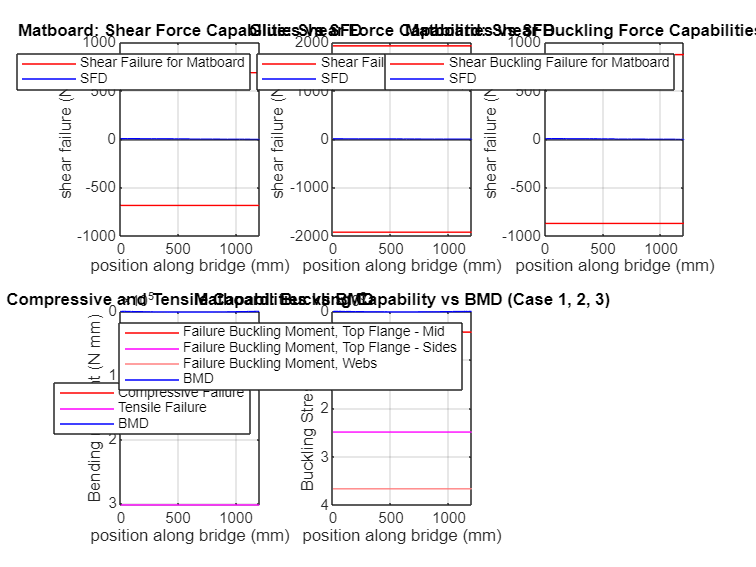

figure;

% Subplot 1: Shear Failure vs Shear Capability (Matboard)
subplot(2, 3, 1);
plot(x, Vf_shear, 'red');
hold on;
plot(x, SFE, 'blue');
plot(x, -1 .* Vf_shear, 'red');
xlabel("position along bridge (mm)");
ylabel("shear failure (N)");
yline(0);
title('Matboard: Shear Force Capabilities vs SFD');
legend('Shear Failure for Matboard', 'SFD', 'Location', 'northeast');
grid;

% Subplot 2: Shear Failure for Glue
subplot(2, 3, 2);
plot(x, Vf_glue, 'red');
hold on;
plot(x, SFE, 'blue');
plot(x, -1 .* Vf_glue, 'red');
xlabel("position along bridge (mm)");
ylabel("shear failure (N)");
yline(0);
title('Glue: Shear Force Capabilities vs SFD');
legend('Shear Failure for Glue', 'SFD', 'Location', 'northeast');
grid;

% Subplot 3: Shear Buckling Capabilities vs SFD
subplot(2, 3, 3);
plot(x, Vf_buckV, 'red');
hold on;
plot(x, SFE, 'blue');
plot(x, -1 .* Vf_buckV, 'red');
xlabel("position along bridge (mm)");
ylabel("shear failure (N)");
yline(0);
title('Matboard: Shear Buckling Force Capabilities vs SFD');
legend('Shear Buckling Failure for Matboard', 'SFD');
grid;

% Subplot 4: Tension, Compression, and BMD
subplot(2, 3, 4);
plot(x, Mf_comp, 'red');
hold on;
plot(x, Mf_tens, 'magenta');
plot(x, BME, 'blue');
set(gca, 'YDir', 'reverse');
xlabel("position along bridge (mm)");
ylabel("Bending moment (N mm)");
title('Compressive and Tensile Capabilities vs BMD');
legend('Compressive Failure', 'Tensile Failure', 'BMD', 'Location', 'east');
grid;

% Subplot 5: Matboard Local Buckling Moment vs BMD
subplot(2, 3, 5);
plot(x, Mf_buck1, 'red');
hold on;
plot(x, Mf_buck2, 'magenta');
plot(x, Mf_buck3, 'Color', '#FF8080');
set(gca, 'YDir', 'reverse');
plot(x, BME, 'blue');

xlabel("position along bridge (mm)");
ylabel("Buckling Stress (MPa)");
title('Matboard: Buckling Capability vs BMD (Case 1, 2, 3)');
legend('Failure Buckling Moment, Top Flange - Mid', ...
       'Failure Buckling Moment, Top Flange - Sides', ...
       'Failure Buckling Moment, Webs', 'BMD', 'Location', 'northeast');
grid;

## Functions

function [ybar, ytop, ybot, I, Qcent, Qglue] = properties(tfb, tfh, wb, wh, gtb, gth, bfb, bfh)
% calcuates geometric properties
% input: known length based on design 0
% output: ybar, ytop, ybot, I, Qcent, Qglue (1x1201 row vector to indicate each of them at different cross sections)

% Get y bar (y)
% calculate area
tfa = tfb .* tfh;
gta = gtb .* gth;
wa = wb .* wh;
bfa = bfb .* bfh;
Atot = tfa + gta .* 2 + wa .* 2 + bfa;      % Total area (2 webs + 2 gt + bf + tf)

% calculate centroid from bottom
y_tf = wh + gth ./ 2;
y_gt = wh - gth ./ 2;
y_w = wh ./ 2;
y_bf = bfh ./ 2;

% calculate centroid, ybot, ytop
htot = wh + tfh;
ybar = (tfa .*  y_tf + (gta .* y_gt) .* 2 + (wa .* y_w) .* 2 + bfa .* y_bf) ./ Atot;
ytop = htot - ybar;
ybot = ybar;

% calculate I
% calculate centroidal distance from ybar
d_tf = abs(y_tf - ybar);
d_gt = abs(y_gt - ybar);
d_w = abs(y_w - ybar);
d_bf = abs(y_bf - ybar);

% calculate each one's I, 
I_tf = (tfb .* (tfh .^3)) ./ 12 + (tfa .* (d_tf .^2));
I_w = (wb .* (wh .^3)) ./ 12 + (wa .* (d_w .^ 2));
I_gt = (gtb .* (gth .^3)) ./ 12 + (gta .* (d_gt .^ 2));
I_bf = (bfb .* (bfh .^3)) ./ 12 + (bfa .* (d_bf .^ 2));

% calculate I total
I = I_tf + I_w .* 2 + I_gt .* 2 + I_bf;

% calculate Qglue
Qglue = tfa .* d_tf;

% calculate Qcent
parta = wb .* ybar;
d_part = ybar ./ 2;
Qcent = parta .* d_part .* 2 + bfa .* d_bf;

end